%SINAIS ELEMENTARES


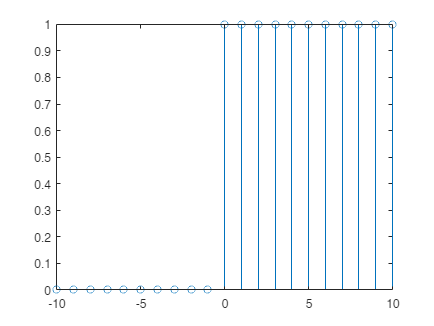

n=-10:10;
degrau = @(nn) (nn>=0)*1;
u = degrau(n);
stem(n,u)

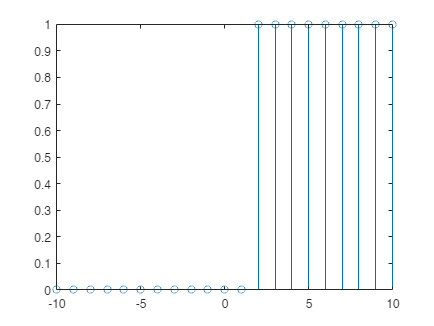

%a) n0 = 2 ou seja adiantado duas unidades
n0 = 2;
u1 = degrau(n - n0);
stem(n, u1)

%b)
n = -5:10; %intervalo que se pretende
n1 = 1;
u2 = degrau(n-n1);
x = (1/3).^(n-1).*u2; %funcao 3(1/3)^n u[n-1]
valor_em_n1 = x(n == 1) %x[1]

valor_em_n1 = 1

valor_em_n2 = x(n == 2);%x[2]
output_fracao_n2 = rats(valor_em_n2) %valor de x[2] em fracao

output_fracao_n2 = '      1/3     '

%c) valor de x[10]
valor_em_n10 = x(n==10) 

valor_em_n10 = 5.0805e-05

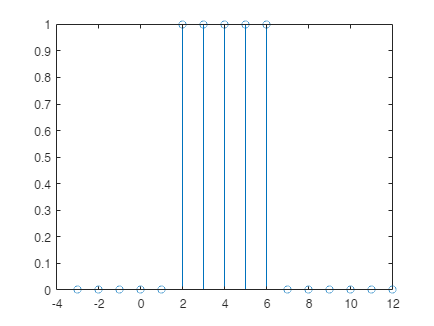

%1.2;
degrau = @(nn) (nn >= 0) * 1;

pulso_retangular = @(n) degrau(n - 2) - degrau(n - 7);
n_intervalo = -3:12;

valores_pulso = pulso_retangular(n_intervalo);

stem(n_intervalo, valores_pulso);


%b)

pulso_retangular_n7= pulso_retangular(n==7)

pulso_retangular_n7 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%CONVULUÇÂO 1D e 2D
degrau = @(nn) (nn >= 0) * 1;
pulso_retangular2 =@(n) degrau(n - 5) - degrau(n - 10);
n = -5:40;

vals_pulso2 = pulso_retangular2(n)

vals_pulso2 =      0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


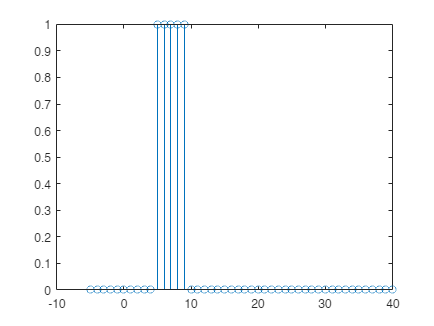

stem(n, vals_pulso2)

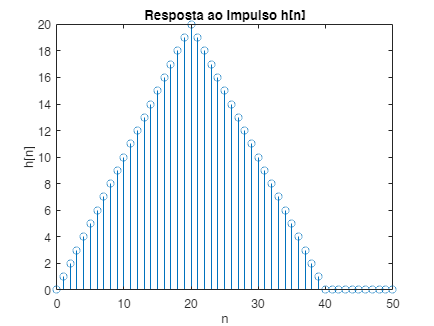


% Definir a função anônima para h[n]
fh = @(n) (n >= 0 & n <= 20) .* n + (n >= 21 & n <= 39) .* (40 - n) + (~((n >= 0 & n <= 20) | (n >= 21 & n <= 39))) .* 0;

% Criar h para n=0:50
n_h = 0:50;
h = fh(n_h);

% Plotar h
stem(n_h, h);
xlabel('n');
ylabel('h[n]');
title('Resposta ao Impulso h[n]');

% Comprimentos dos vetores x e h
Nx = length(vals_pulso2);
Nh = length(h);

% Limites para a saída
x_0 = 5;
h_0 = 0;
x_1 = 40;
h_1 = 50;

% Calcular a saída usando conv
y = conv(vals_pulso2, h);

% Ajustar a saída para o intervalo correto
inicio = x_0 + h_0;
fim = x_1 + h_1;
saida = y(inicio:fim);

% Exibir a saída
disp('Saída do sistema:');

Saída do sistema:


disp(saida);

  Columns 1 through 22

     0     0     0     0     0     0     0     1     3     6    10    15    20    25    30    35    40    45    50    55    60    65

  Columns 23 through 44

    70    75    80    85    90    93    94    93    90    85    80    75    70    65    60    55    50    45    40    35    30    25

  Columns 45 through 66

    20    15    10     6     3     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 67 through 86

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



y(1:11)

ans =      0     0     0     0     0     0     0     0     0     0     0



val_em6 = y(n == 6)

val_em6 = 1

%parte das imagens vai ficar no pratica3_2